# Nonlinear Kalman filters

The purpose of this document is to use the **Matlab** environment to design and implement an Extended and an Unscented Kalman Filter. Make sure you've read Chapters 13 and 14 first and then check this document before doing the homework.

We will use a simple nonlinear system with nonlinear measurements for this manual:


$$x_{k+1}^a =-\cos \left(x_k^b \right)+w^a$$



$$x_{k+1}^b =\sin \left(x_k^a \right)+w^b$$


$y_k ={\left(x_k^a +x_k^b \right)}^2$+ v

with:


$$\begin{array}{l}
w^a ~\left(0,0\ldotp 1\right)\\
w^a ~\left(0,0\ldotp 1\right)\\
v\;\;\;~\left(0,0\ldotp 01\right)
\end{array}$$


and initial error covariance matrix:


$$P=\left\lbrack \begin{array}{cc}
1 & 0\\
0 & 1
\end{array}\right\rbrack$$


## Extended Kalman Filter

We will run both filters for 100 time steps. We will start by initializing the variables that will be used by both filters:

% Initialize the random number generator so we can replicate the results
rng('default');

time_steps = 100;
X_true = zeros([2, time_steps]);
y = zeros([1, time_steps]);

w_variance = 0.1;
v_variance = 0.01;

Q = [w_variance, 0; 0, w_variance];
R = v_variance;

Here we will initialize the EKF specific variables:

X_est_EKF = zeros([2, time_steps]);
P_EKF = [1, 0; 0, 1];
P_store_EKF = zeros([4, time_steps]);
P_store_EKF(:, 1) = P_EKF(:);

To get the Jacobians we will define some functions. The functions are defined in the files 'getF.m' and 'getH.m'. Open the files to check the implementation.

We are now ready to simulate the system:

for i = 2:time_steps
    % Update the true and estimated states
    w_a = sqrt(w_variance) * randn();
    w_b = sqrt(w_variance) * randn();
    
    X_true(1, i) = -cos(X_true(2, i - 1)) + w_a;
    X_true(2, i) =  sin(X_true(1, i - 1)) + w_b;
    
    X_est_EKF(1, i) = -cos(X_est_EKF(2, i - 1));
    X_est_EKF(2, i) =  sin(X_est_EKF(1, i - 1));
    
    % Update the error covariance matrix
    F = getF_EKF(X_est_EKF(:, i));
    P_EKF = F*P_EKF*F' + Q;
    
    % Get measurement
    v = sqrt(v_variance) * randn();
    y(i) = (X_true(1, i) + X_true(2, i))^2 + v;
    
    % Get expected measurement
    y_exp = (X_est_EKF(1, i) + X_est_EKF(2, i))^2;
    
    % Compute Kalman gain
    H = getH_EKF(X_est_EKF(:, i));
    K = P_EKF*H'/(H*P_EKF*H' + R);
    
    % Correct state estimate
    X_est_EKF(:, i) = X_est_EKF(:, i) + K*(y(i) - y_exp);
    
    % Update the error covariance matrix
    P_EKF = (eye(2) - K*H)*P_EKF;
    P_store_EKF(:, i) = P_EKF(:);
end

## Unscented Kalman Filter

Multiple ways of selecting sigma points have been propossed since the inception of the UKF. Here we will use a set of 2n sigma points, as shown in the book (page 441, eq. 14.29). We 'll use the functions 'system_f.m' and 'measurement_h.m' for the f and h functions respectively.

We'll start by initializing the UKF specific variables:

X_est_UKF = zeros([2, time_steps]);
P_UKF = [1, 0; 0, 1];
P_store_UKF = zeros([4, time_steps]);
P_store_UKF(:, 1) = P_UKF(:);

% For sigma points
n = size(X_est_UKF, 1);
m = size(y, 1);

x_hat = zeros(n, 2*n);
s_hat = zeros(n, 2*n);
y_hat = zeros(m, 2*n);

We are now ready to simulate the system:

% We already have the true state and measurements from the EKF
for i = 2:time_steps
    % Get L matrix (L*L' = P)
    L = chol(P_UKF)';
    
    % Get sigma points
    x_hat(:, 1) = X_est_UKF(:, i - 1) + sqrt(n) * L(:, 1);
    x_hat(:, 2) = X_est_UKF(:, i - 1) - sqrt(n) * L(:, 1);
    x_hat(:, 3) = X_est_UKF(:, i - 1) + sqrt(n) * L(:, 2);
    x_hat(:, 4) = X_est_UKF(:, i - 1) - sqrt(n) * L(:, 2);
    
    % Propagate sigma points
    for j = 1 : size(x_hat, 2)
        s_hat(:, j) = system_f(x_hat(:, j));
    end
    
    % Update estimated state
    s_mean = sum(s_hat, 2) / (2 * n);
    X_est_UKF(:, i) = s_mean;
    
    % Update the error covariance matrix
    P_UKF = Q;
    for j = 1 : size(x_hat, 2)
        ds = s_hat(:, j) - s_mean;
        P_UKF = P_UKF + (ds*ds') / (2 * n);
    end
    
    % Get new L matrix (L*L' = P)
    L = chol(P_UKF)';
    
    % Get new sigma points
    x_hat(:, 1) = X_est_UKF(:, i) + sqrt(n) * L(:, 1);
    x_hat(:, 2) = X_est_UKF(:, i) - sqrt(n) * L(:, 1);
    x_hat(:, 3) = X_est_UKF(:, i) + sqrt(n) * L(:, 2);
    x_hat(:, 4) = X_est_UKF(:, i) - sqrt(n) * L(:, 2);
    
    % Run sigma points through measurement function
    for j = 1 : size(x_hat, 2)
        y_hat(j) = measurement_h(x_hat(:, j));
    end
    
    % Get measurement mean
    y_mean = sum(y_hat, 2) / (2 * n);
    
    % Compute measurement covariance matrix
    P_y = R;
    for j = 1 : size(y_hat, 2)
        dy = y_hat(j) - y_mean;
        P_y = P_y + (dy*dy')  / (2 * n);
    end
    
    % Compute cross covariance
    P_xy = 0;
    for j = 1 : size(x_hat, 2)
        dx = x_hat(:, j) - X_est_UKF(:, i);
        dy = y_hat(j) - y_mean;
        P_xy = P_xy + (dx*dy');
    end
    P_xy = P_xy / (2 * n);
        
    % Compute Kalman gain
    K = P_xy/P_y;
    
    % Get expected measurement
    y_exp = y_mean;
    
    % Correct state estimate
    X_est_UKF(:, i) = X_est_UKF(:, i) + K*(y(i) - y_exp);
    
    % Update the error covariance matrix
    P_UKF = P_UKF - K*P_y*K';
    P_store_UKF(:, i) = P_UKF(:);
end

Let's plot the estimation results state:

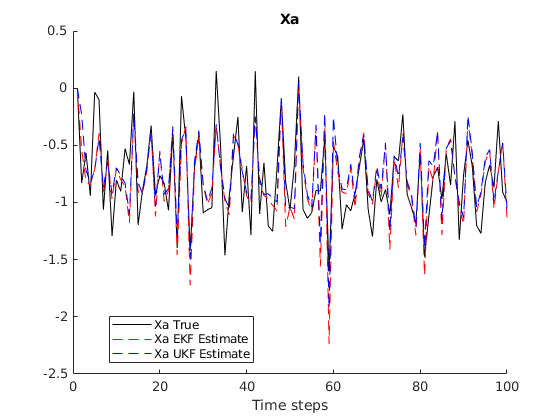

figure
hold on
plot(X_true(1, :), 'k-')
plot(X_est_EKF(1, :), 'r--')
plot(X_est_UKF(1, :), 'b--')
hold off
legend('Xa True', 'Xa EKF Estimate', 'Xa UKF Estimate', 'Location','best');
title('Xa');
xlabel('Time steps');

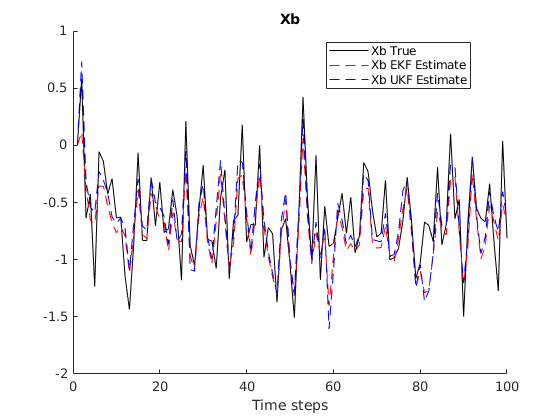


figure
hold on
plot(X_true(2, :), 'k-')
plot(X_est_EKF(2, :), 'r--')
plot(X_est_UKF(2, :), 'b--')
hold off
legend('Xb True', 'Xb EKF Estimate', 'Xb UKF Estimate', 'Location','best');
title('Xb');
xlabel('Time steps');

Let's also plot here the error and error levels of the two filters:

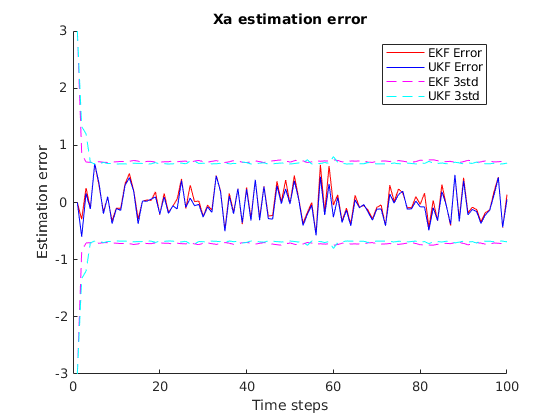

std_Xa_EKF = sqrt(P_store_EKF(1, :));
std_Xb_EKF = sqrt(P_store_EKF(4, :));

std_Xa_UKF = sqrt(P_store_UKF(1, :));
std_Xb_UKF = sqrt(P_store_UKF(4, :));

figure
hold on
plot(X_true(1, :) - X_est_EKF(1, :), 'r-')
plot(X_true(1, :) - X_est_UKF(1, :), 'b-')
plot(3*std_Xa_EKF, 'm--')
plot(3*std_Xa_UKF, 'c--')
plot(-3*std_Xa_EKF, 'm--')
plot(-3*std_Xa_UKF, 'c--')
hold off
legend('EKF Error', 'UKF Error', 'EKF 3std', 'UKF 3std', 'Location','best');
title('Xa estimation error');
ylabel('Estimation error');
xlabel('Time steps');

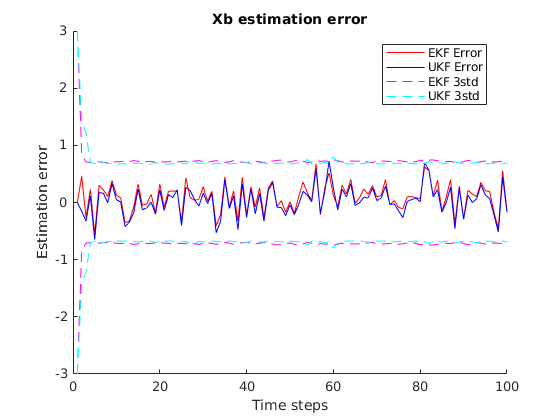


figure
hold on
plot(X_true(2, :) - X_est_EKF(2, :), 'r-')
plot(X_true(2, :) - X_est_UKF(2, :), 'b-')
plot(3*std_Xb_EKF, 'm--')
plot(3*std_Xb_UKF, 'c--')
plot(-3*std_Xb_EKF, 'm--')
plot(-3*std_Xb_UKF, 'c--')
hold off
legend('EKF Error', 'UKF Error', 'EKF 3std', 'UKF 3std', 'Location','best');
title('Xb estimation error');
ylabel('Estimation error');
xlabel('Time steps');

As you can see, for a such a simple system, both filters have comparable performance.